# Computational Methods in Physics (PHY4605) - **Arrays and Matrices**

## Overview

MATLAB can deal with data of any dimensions and sizes, known as arrays. An **array** is a collection of data values and can have any number of dimensions and sizes, which is an umbrella term that can be a scalar, vector, matrix or page. A **scalar** is a single value that does not have any dimension. Scalars are often used to represent constants, coefficients, or magnitudes of vectors. A **vector** is a one-dimensional array with either one row or one column. Vectors are often used to represent quantities that have both magnitude and direction, such as force or velocity. A **matrix** is a two-dimensional array with at least one row and one column. Matrices are often used to represent linear equations, transformations, or operations on data. A **page** is a slice of a three-dimensional array along the third dimension. Pages are useful for storing multiple matrices that have the same size and meaning.

## Vectors

A vector is a special type of array, having only one row or one column. You can initialize vectors either explicitly:

a = [1, 2, 3]

a =      1     2     3


b = [4, 5]

b =      4     5


c = [a, -b]

c =      1     2     3    -4    -5


d = [10; 12; 20]

d =     10
    12
    20


You can do the same using the colon operator as well:

x = 1 : 10

x =      1     2     3     4     5     6     7     8     9    10


x = 1 : 0.5 : 4

x =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


x = 0 : -2 : -5

x =      0    -2    -4


All of the vectors examined so far are row vectors. To generate the column vectors, you need to transpose such vectors:

y = [1 4 8 0 -1]'

y =      1
     4
     8
     0
    -1


x'

ans =      0
    -2
    -4


We can refer to particular elements of a vector by means of subscripts:

r = rand(1, 7)

r =     0.6912    0.5646    0.1776    0.4704    0.7272    0.7639    0.8241


r(3)

ans = 0.6051

r(2:4)

ans =     0.1661    0.6051    0.0993


r([1 7 2 6])

ans =     0.5682    0.7205    0.1661    0.3675


Use an empty vector to remove elements from a vector:

r([1 7 2]) = []

Matrix index is out of range for deletion.

## Matrices

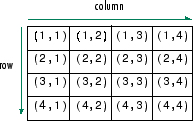

A matrix may be thought of as a table consisting of rows and columns. You create a matrix just as you do a vector, except that a semicolon is used to indicate the end of a row:

a = [1, 2, 3; 4, 5, 6; 7, 8, 9; 11, 12, 13]

a =      1     2     3
     4     5     6
     7     8     9
    11    12    13


A matrix may be transposed:

m = a'

m =      1     4     7    11
     2     5     8    12
     3     6     9    13


A matrix can be constructed from column vectors of the same length:

x = 0 : 30 : 180;
t = [x' sin(x*pi/180)']

t =          0         0
   30.0000    0.5000
   60.0000    0.8660
   90.0000    1.0000
  120.0000    0.8660
  150.0000    0.5000
  180.0000    0.0000


The colon operator provides for very efficient ways of handling matrices, for examples:

a(4, 2)

ans = 12

a(2:3, 1:2)

ans =      4     5
     7     8


m(1:2, 2:end)

ans =      4     7    11
     5     8    12


a(1:2, 2:3) = 100*ones(2)

a =      1   100   100
     4   100   100
     7     8     9
    11    12    13


On the right-hand side of an assignment:

b = a(:)

gives all the elements of a strung out by columns in one long column vector. 

However, on the left-hand side of an assignment, `c(:)` reshapes a matrix and `c `must already exist. Then `a(:)` denotes a matrix with the same dimensions (shape) as `c`, but with new contents taken from the right-hand side:

c = NaN(6, 2)
c(:) = a

the contents of `a` are strung out into one long column and then fed into `c` by columns.

The same effect can be achieved using the `reshape` function. For example, the call to the function `reshape(A, 5, 2) ` reshapes `A` into a 5-by-2 matrix. The new matrix must have at least 2 dimensions and the product of the dimension sizes must be the same as the number of elements of `A`. Another example:

A = 2 : 2 : 20
reshape(A, 5, 2)

### Matrix Functions

There is a group of functions to generate ‘elementary’ matrices which are used in a number of applications. See `help elmat`. For example, the functions `NaN,` `zeros`, `ones` and `rand` generate matrices of empty values ('not a number' or `NaN`), `1`’s, `0`’s and random numbers, respectively. With a single argument $n$, they generate $n\times n$ (square) matrices. With two arguments $n$ and $m$ they generate $n\times m$ matrices.

NaNs = NaN(4)

NaNs =    NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN


Zeros = zeros(4)

Zeros =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Ones = ones(3)

Ones =      1     1     1
     1     1     1
     1     1     1


Randoms = rand(3)

Randoms =     0.6569    0.9983    0.7661
    0.1406    0.3656    0.6694
    0.4704    0.9515    0.4449


Many of the other functions operate on matrices column by column, e.g.:

a = randi([0, 1], 5, 'logical')

a = 5×5 logical array
   0   1   0   1   0
   1   0   0   0   1
   0   1   0   1   1
   0   1   1   1   0
   0   1   1   1   1


all(a)

ans = 1×5 logical array
   0   0   0   0   0


any(a)

ans = 1×5 logical array
   1   1   1   1   1


For each column of a where all the elements are `true` (non-zero) `all` returns `1`, otherwise it returns `0 `(acts as an `AND` operator`)`. To test if `all` the elements of `a` are `true`, use `all` twice. In this example, the statement:

all(all(a))

returns `0` because some of the elements of `a` are `0`. The same rule applies for `any` that acts as a logical `OR` operator instead of `AND`.

Here are some functions for manipulating matrices:

b = randi(100, [6, 8])

b =     77    67    28    36    47     2    46   100
    52    50    11    87    69    27    76    10
     3    59    76    64    47    69    70    32
    85    57    16    23    68    54    66    67
    77    70    57    58    53    15    91    93
    25     8    59    24    76    80    45    17


diag(b)    % Extracts or creates a diagonal

ans =     77
    50
    76
    23
    53
    80


fliplr(b)  % Flips from left to right

ans =    100    46     2    47    36    28    67    77
    10    76    27    69    87    11    50    52
    32    70    69    47    64    76    59     3
    67    66    54    68    23    16    57    85
    93    91    15    53    58    57    70    77
    17    45    80    76    24    59     8    25


flipud(b)  % Flips from top to bottom

ans =     25     8    59    24    76    80    45    17
    77    70    57    58    53    15    91    93
    85    57    16    23    68    54    66    67
     3    59    76    64    47    69    70    32
    52    50    11    87    69    27    76    10
    77    67    28    36    47     2    46   100


rot90(b)   % Rotates

ans =    100    10    32    67    93    17
    46    76    70    66    91    45
     2    27    69    54    15    80
    47    69    47    68    53    76
    36    87    64    23    58    24
    28    11    76    16    57    59
    67    50    59    57    70     8
    77    52     3    85    77    25


tril(b)    % Extracts the lower triangular part

ans =     77     0     0     0     0     0     0     0
    52    50     0     0     0     0     0     0
     3    59    76     0     0     0     0     0
    85    57    16    23     0     0     0     0
    77    70    57    58    53     0     0     0
    25     8    59    24    76    80     0     0


triu(b)    % Extracts the upper triangular part

ans =     77    67    28    36    47     2    46   100
     0    50    11    87    69    27    76    10
     0     0    76    64    47    69    70    32
     0     0     0    23    68    54    66    67
     0     0     0     0    53    15    91    93
     0     0     0     0     0    80    45    17


While, here are some of MATLAB’s more advanced matrix functions.

c = randi(100, 3)
det(c)  % Determinant
eig(c)  % Eigenvalue decomposition
expm(c) % Matrix exponential, i.e., e^A, where A is a matrix
inv(c)  % Inverse
lu(c)   % LU factorization (into lower and upper triangular matrices)
qr(c)   % Orthogonal factorization
svd(c)  % Singular value decomposition

### Vectorization

MATLAB is optimized for operations involving matrices and vectors. The process of revising loop-based, scalar-oriented code to use MATLAB matrix and vector operations is called *vectorization*.

This code computes the sine of 10,000,001 values ranging from 0 to 10:

tic
i = 0;
for t = 0 : 0.000001 : 10
    i = i + 1;
    y(i) = sin(t);
end
toc

Elapsed time is 0.408910 seconds.


This is a vectorized version of the same code:

tic
t = 0 : 0.000001 : 10;
y = sin(t);
toc

Elapsed time is 0.082759 seconds.


Array operators perform the same operation for all elements in the data set. These types of operations are useful for repetitive calculations. For example, suppose you collect the volume (`V`) of various cones by recording their diameter (`D`) and height (`H`). If you collect the information for just one cone, you can calculate the volume for that single cone:

D = 10
H = 25
V = 1/12 * pi * (D^2) * H

Now, collect information on 10,000 cones. The vectors `D` and `H` each contain 10,000 elements, and you want to calculate 10,000 volumes. In most programming languages, you need to set up a loop similar to this MATLAB code:

D = randi(20, 1, 10000)
H = randi(30, 1, 10000)
for n = 1 : 10000
    V(n) = 1/12*pi*(D(n)^2)*H(n);
end
V

With MATLAB, you can perform the calculation for each element of a vector with similar syntax as the scalar case:

V = 1/12 * pi * (D.^2) .* H

### Matrix Operations

Matrix addition and subtraction are defined in the same way as the equivalent array operations, i.e., element by element. Matrix multiplication, however, is quite different. 

a = [1 2; 3 4]

a =      1     2
     3     4


b = [5 6; 0 -1]

b =      5     6
     0    -1


m1 = a * b 

m1 =      5     4
    15    14


m2 = a .* b

m2 =      5    12
     0    -4


Note the important difference between the array operation `a .* b` and the matrix operation `a * b`.

The matrix operation $A^2$ means $A\times A$, where $A$ must be a square matrix. The operator `^` is used for matrix exponentiation, e.g.:

p1 = a ^ 2

p1 =      7    10
    15    22


p2 = a .^ 2

p2 =      1     4
     9    16


`a ^ 2 `is the same as `a * a`.  Again, note the difference between the array operation `a .^ 2 `and the matrix operation `a ^ 2`.

### Linear Equations

A problem that often arises in scientific applications is the solution of a system of linear equations, e.g.:


$$\begin{array}{l}
3x_1 +2x_2 -x_3 =10\\
-x_1 +3x_2 +2x_3 =5\\
x_1 -x_2 -x_3 =-1\ldotp 
\end{array}$$


MATLAB was designed to solve a system like this directly and very easily, as we shall now see. If we define the matrix of coefficients, $A$, the vectors of unknowns, $x$, and the right-hand side, $b$, as:


$$A=\left\lbrack \begin{array}{ccc}
3 & 2 & -1\\
-1 & 3 & 2\\
1 & -1 & -1
\end{array}\right\rbrack ,\;\;x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
10\\
5\\
-1
\end{array}\right\rbrack$$


we can write the above system of three equations in matrix form as:


$$\left\lbrack \begin{array}{ccc}
3 & 2 & -1\\
-1 & 3 & 2\\
1 & -1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10\\
5\\
-1
\end{array}\right\rbrack$$


or even more concisely as the single matrix equation $\textrm{Ax}=b$. The solution may then be written as $x=A^{-1} b$. The system can be solved by the following:

A = [3, 2, -1; -1, 3, 2; 1, -1, -1];
b = [10 5 -1]';
x = A \ b

x =    -2.0000
    5.0000
   -6.0000


x = inv(A) * b

x =    -2.0000
    5.0000
   -6.0000


which gives $x_1 =-2,{\;x}_2 =5,\;x_3 =-6$. Notice that the left division operator (`\)` is used. You can think of the matrix operation `A \ `b as ‘$b$ divided by $A$’, or as ‘the inverse of $A$ multiplied by $b$’.

### Physics Pinpoint 🔎: Kirchhoff's Rules

Kirchhoff's Rules are fundamental in analyzing electrical circuits. They allow us to calculate unknown currents, voltages, and resistances in complex circuits by formulating them as a system of linear equations.

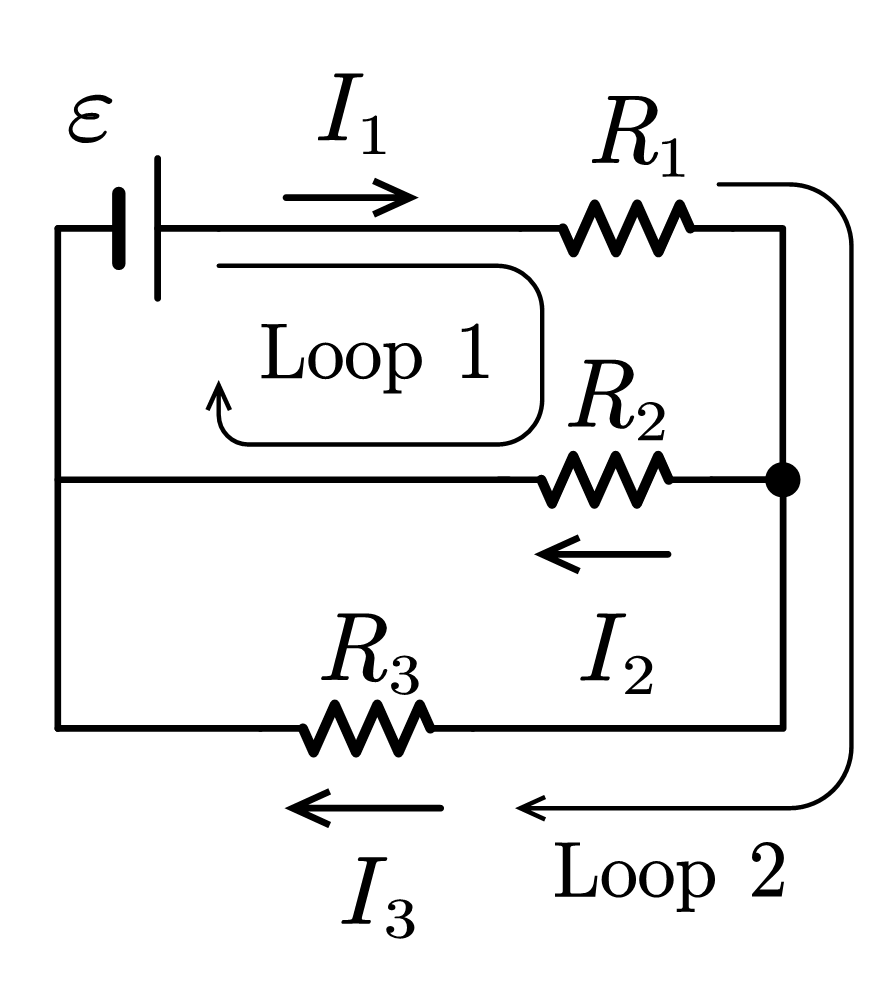

Consider a simple circuit with three resistors ($R_1 =4\;\Omega$, $R_2 =6\;\Omega$ and $R_3 =8\;\Omega$), connected in a combination of series and parallel, powered by a voltage source ($V=12\;\mathrm{V}$). We need to calculate the currents flowing through each branch of the circuit, namely $I_1$, $I_2$ and $I_3$.

- Applying the junction rule at the node: $I_1 =I_2 +I_3$$\Longrightarrow$$I_1 -I_2 -I_3 =0$

- Applying the loop rule around the inner loop 1: $V-R_1 I_1 -R_2 I_2 =0$$\Longrightarrow$$12-4I_1 -6I_2 =0$ $\Longrightarrow$ $4I_1 +6I_2 +0I_3 =12$

- Applying the loop rule around the outer loop 2: $V-R_1 I_1 -R_3 I_3 =0$$\Longrightarrow$$12-4I_1 -8I_3 =0$ $\Longrightarrow$ $4I_1 +0I_2 +8I_3 =12$

Now, we have a system of linear equations:


$$\left\lbrack \begin{array}{ccc}
I_1  & {-I}_2  & -I_3 \\
4I_1  & 6I_2  & 0I_3 \\
4I_1  & 0I_2  & 8I_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
12\\
12
\end{array}\right\rbrack$$
 
$$\Longrightarrow$$
 
$$\left\lbrack \begin{array}{ccc}
1 & -1 & -1\\
4 & 6 & 0\\
4 & 0 & 8
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
I_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
12\\
12
\end{array}\right\rbrack$$


The system can be solved by the following:

A = [1, -1, -1 
     4, 6, 0;   
     4, 0, 8] 

A =      1    -1    -1
     4     6     0
     4     0     8


b = [0; 12; 12]

b =      0
    12
    12


I = A \ b;
fprintf('I1 = %.2f A\n', I(1));

I1 = 1.62 A


fprintf('I2 = %.2f A\n', I(2));

I2 = 0.92 A


fprintf('I3 = %.2f A\n', I(3));

I3 = 0.69 A


## Multidimensional Arrays

Multidimensional arrays are an extension of 2-D matrices and use additional subscripts for indexing. A 3-D array, for example, uses three subscripts. The first two are just like a matrix, but the third dimension represents *pages* or *sheets* of elements.

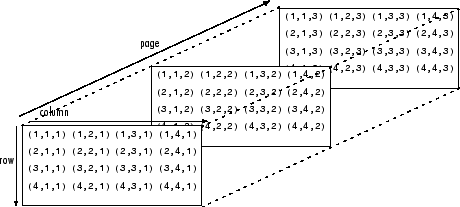

A multidimensional array can be created by creating a 2-D matrix first, and then extending it. For example, first define a 3-by-3 matrix as the first page in a 3-D array:

A = [1 2 3; 4 5 6; 7 8 9]

Assign another 3-by-3 matrix to the index value 2 in the third dimension to add a second 'page'. The syntax A`(:,:,2)` uses a colon in the first and second dimensions to include all rows and all columns from the right-hand side of the assignment:

A(:,:,2) = [10 11 12; 13 14 15; 16 17 18]

The `cat` function can be a useful tool for building multidimensional arrays. For example, create a new 3-D array `B` by concatenating `A` with a third page. The first argument indicates which dimension to concatenate along:

B = cat(3,A,[3 2 1; 0 9 8; 5 3 7])

To access elements in a multidimensional array, use integer subscripts just as you would for vectors and matrices. For example, find the `(1,2,2)` element of `A`, which is in the first row, second column, and second page of `A`: 

A(1,2,2)